# Improving Predictive Models

## 1. Cross Validation

Use 10-fold cross validation to evaluate the various predictive models for the heart disease data.

% Run comparison with holdout validation
compareclassifiers

                                     ResubLoss     Loss  
                                     _________    _______

    kNN                                     0     0.34127
    kNN k=5                           0.22222     0.24713
    Weighted kNN k=5                        0     0.24713
    Tree                             0.078947     0.28237
    Pruned tree                       0.14035     0.20004
    Tree (all predictors)            0.055556     0.23531
    Pruned tree (all predictors)      0.10819     0.21179
    NB                                0.29825     0.20002
    NB kernel                         0.26023      0.1765
    NB (all predictors)               0.20468     0.11767
    NB kernel (all predictors)        0.19591      0.1412
    Linear DA                         0.27193      0.1765
    Quadratic DA                      0.24854      0.2706
    Linear SVM                        0.30117     0.16475
    Gaussian SVM                      0.26023     0.16473
    Linear SV

% Add variable to hold cross validation errors
results.kFoldLoss = zeros(height(results),1);

% Remove pruned trees because the cross validation cannot apply for the pruned trees
results([5 7],:) = []

results = 15×3 table
                                     ResubLoss     Loss      kFoldLoss
                                     _________    _______    _________

    kNN                                     0     0.34127        0    
    kNN k=5                           0.22222     0.24713        0    
    Weighted kNN k=5                        0     0.24713        0    
    Tree                             0.078947     0.28237        0    
    Tree (all predictors)            0.055556     0.23531        0    
    NB                                0.29825     0.20002        0    
    NB kernel                         0.26023      0.1765        0    
    NB (all predictors)               0.20468     0.11767        0    
    NB kernel (all predictors)        0.19591      0.1412        0    
    Linear DA                         0.27193      0.1765        0    
    Quadratic DA                      0.24854      0.2706        0    
    Linear SVM                        0.30117     0.164

% Make a cross validation partition
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'kFold',10)

part = K-겹 교차 검증 분할
   NumObservations: 427
       NumTestSets: 10
         TrainSize: 385  384  384  384  384  384  384  384  385  385
          TestSize: 42  43  43  43  43  43  43  43  42  42

### 1.1. Create cross-validated models

Note that the cross-validated models are only used to evaluate performance. The fitted models do not have a `predict` method. 

% Divide the data into training+validation and test sets
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,"HoldOut",0.2);
trValidx = training(part);
trValData = heartdataNum(trValidx,:)% trValData is to build a model

trValData = 342×12 table
      Age      Cholesterol    ExerciseDuration     METs     RestingHeartRate    RestingSystolic    RestingDiastolic    MaxHeartRate    PeakExSystolic    PeakExDiastolic    InducedSTDep    HeartDisease
    _______    ___________    ________________    ______    ________________    _______________    ________________    ____________    ______________    _______________    ____________    ____________

    0.70833      0.37151          0.48649         0.6875        0.25316             0.49074            0.58333           0.60902          0.67949            0.61538           0.41071         false    
    0.79167      0.51955          0.43243         0.6875         0.3038             0.62963            0.66667           0.29323          0.48718            0.61538           0.26786         true     
    0.16667      0.41899          0.62162         0.9375        0.55696             0.35185            0.46667           0.88722          0.71154            0.40385      

testData = heartdataNum(~trValidx,:)  % Assume that testData is newly measured data.

testData = 85×12 table
      Age      Cholesterol    ExerciseDuration     METs     RestingHeartRate    RestingSystolic    RestingDiastolic    MaxHeartRate    PeakExSystolic    PeakExDiastolic    InducedSTDep    HeartDisease
    _______    ___________    ________________    ______    ________________    _______________    ________________    ____________    ______________    _______________    ____________    ____________

    0.79167      0.36034          0.37838            0.5        0.48101             0.25926                0.5           0.45113          0.35897            0.51923           0.46429         true     
    0.70833      0.43017          0.35135         0.4375        0.44304             0.35185            0.91667           0.58647          0.23077            0.42308              0.25         true     
    0.58333      0.25698          0.36216         0.4375        0.58228             0.44444            0.66667           0.59398          0.61538            0.47115        


% Divide the training+validation data into training and validation sets
part2 = cvpartition(trValData.HeartDisease,"HoldOut",0.2);
tridx = training(part2);
trdata = trValData(tridx,:);
valdata = trValData(~tridx,:);

% Models with 'holdout' do have a predict method for the validation data
mdlknn = fitcknn(trdata,"HeartDisease");
errKNN_tr = resubLoss(mdlknn)

errKNN_tr = 0

errKNN_val = loss(mdlknn,valdata)

errKNN_val = 0.4130

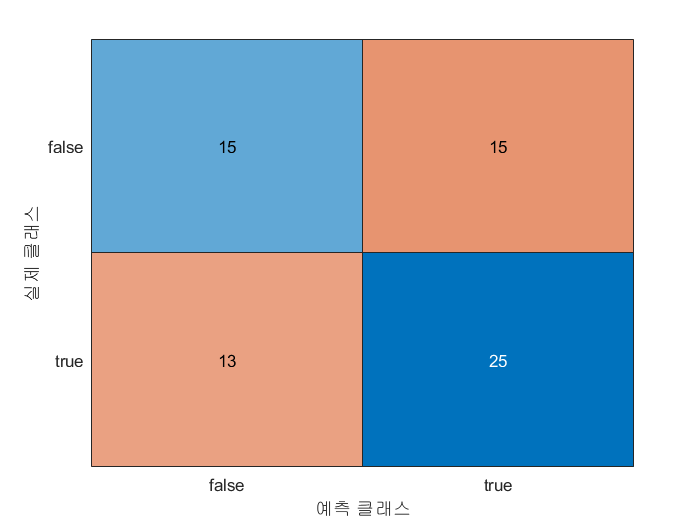


HDpred = predict(mdlknn,valdata);
HDtrue = valdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)


% Models with 'holdout' do have a predict method for the test data
HDpred_test = predict(mdlknn,testData)

HDpred_test = 85×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 



% k-fold
part2 = cvpartition(trValData.HeartDisease,"KFold",10);
mdlknn_kfold = fitcknn(trValData,'HeartDisease','CVPartition',part2)

mdlknn_kfold =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
           ResponseName: 'HeartDisease'
        NumObservations: 342
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [false    true]
         ScoreTransform: 'none'


  Properties, Methods


errKNN_kfold = kfoldLoss(mdlknn_kfold)

errKNN_kfold = 0.3655


% Models with 'kfold' do NOT have a predict method
%HDpred_test_kfold = predict(mdlknn_kfold,testData) % k-fold에서는 predict할 수 있는 기능이 없다 

## 2. Hyperparameter optimization - 모델 내부 설정을 하는 파라미터인데 하이퍼파라미터는 파라미터 중의 하나로써 일단 학습이 시작하면 변하지 않는 값들이다. 대표적 파라미터가 weight인데 따로 설정하는 것이 아니고 일반적으로 그 파라미터들은 데이터로부터 얻어지는 값들이기 때문에 학습이 진행되면 될수록 값이 변한다. 그것을 파라미터라고 하는데 그 중에서 학습 하기 전에 우리가 직접 입력해서 학습 중간에 값이 변하지 않는 파라미터를 하이퍼 파라미터라 한다, 

Hyperparameter optimization is very powerful in that it automatically tune a model. Just do it.

% Divide the data into training and validation sets
load heartdisease.mat
rng(1234)
%evalclusters 비지도 학습 
part = cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2);
tridx = training(part);
trData = heartdataNum(tridx,:);
valData = heartdataNum(~tridx,:);

% Train a kNN model
mdlknn = fitcknn(trData,'HeartDisease');
errKNN_tr = resubLoss(mdlknn)

errKNN_tr = 0

errKNN_val = loss(mdlknn,valData)

errKNN_val = 0.3413

### 2.1. Turn on hyperparameter optimization - 가장 시간이 오래 걸려

Setting '`OptimizeHyperparamters`' to '`auto`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

%mdlknn_HO = fitcknn(trdata,'HeartDisease','OptimizeHyperparameters',"auto");

The command-line output contains information on the evaluated property values and the hyperparameters chosen for the final model.

mdlknn_HO.Distance 

ans = 'seuclidean'

mdlknn_HO.NumNeighbors

ans = 67

The first plot shows the best objective function against the iteration number. The second plot is a model of the objective function against the parameters. You can hide these plots with the '`ShowPlots`' argument.

errKNNHO_tr = resubLoss(mdlknn_HO)

errKNNHO_tr = 0.3029

errKNNHO_val = loss(mdlknn_HO,valdata)

errKNNHO_val = 0.3115

### 2.2. Change optimization options

Make cross validation partition

part = cvpartition(trData.HeartDisease,"KFold",10);

Change the validation to use '`part`' and decrease the number of objective evaluations.

opt = struct('CVPartition',part,'MaxObjectiveEvaluation',20);

Setting '`OptimizeHyperparamters`' to '`all`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

- `DistanceWeight`

- `Exponent`

- `Standardize`

%mdlknn_HO = fitcknn(trData,'HeartDisease','OptimizeHyperparameters','all','HyperparameterOptimizationOptions',opt);

Note that there is only one plot displayed. You will only see the second plot if there are one or two optimization parameters, and if '`Optimizer`' is set to '`bayesopt`'.

|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|     Exponent |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.37135 |       1.211 |     0.37135 |     0.37135 |            1 |  correlation |        equal |            - |        false |


|    2 | Accept |     0.38012 |     0.43765 |     0.37135 |     0.37169 |            1 |    minkowski | squaredinver |       2.3132 |         true |


|    3 | Best   |     0.31287 |     0.28893 |     0.31287 |     0.31542 |          152 |    minkowski |        equal |        1.912 |        false |


|    4 | Accept |     0.32749 |     0.25845 |     0.31287 |     0.31536 |          101 |    chebychev |        equal |            - |         true |


|    5 | Best   |     0.30409 |     0.27058 |     0.30409 |     0.30525 |           94 |    minkowski |        equal |        1.844 |        false |


|    6 | Accept |     0.30994 |     0.37051 |     0.30409 |     0.30925 |           24 |    minkowski |        equal |       1.5375 |        false |


|    7 | Accept |     0.34211 |     0.32481 |     0.30409 |     0.30689 |            2 |    minkowski |        equal |       1.8042 |        false |


|    8 | Accept |     0.31287 |     0.34297 |     0.30409 |     0.30881 |           56 |    minkowski |        equal |       2.0446 |        false |


|    9 | Best   |     0.30117 |     0.29594 |     0.30117 |     0.30272 |           88 |    minkowski |        equal |       0.5515 |        false |


|   10 | Accept |     0.31287 |     0.26007 |     0.30117 |     0.30842 |           78 |    minkowski |        equal |       0.6586 |        false |


|   11 | Accept |     0.32164 |     0.30454 |     0.30117 |     0.30708 |          171 |    minkowski |        equal |       2.8328 |        false |


|   12 | Accept |     0.30702 |     0.30444 |     0.30117 |     0.30696 |           62 |    minkowski |        equal |      0.55478 |        false |


|   13 | Accept |     0.30994 |       0.272 |     0.30117 |     0.30773 |           89 |    minkowski |        equal |      0.61142 |        false |


|   14 | Best   |      0.2924 |     0.26197 |      0.2924 |     0.30471 |           46 |    minkowski |        equal |      0.55532 |        false |


|   15 | Accept |     0.29532 |     0.31623 |      0.2924 |     0.30199 |           43 |    minkowski |        equal |      0.50545 |        false |


|   16 | Accept |     0.30994 |     0.25101 |      0.2924 |     0.30373 |           35 |    minkowski |        equal |      0.50225 |        false |


|   17 | Accept |     0.39181 |     0.19118 |      0.2924 |     0.30359 |            1 |    chebychev |        equal |            - |         true |


|   18 | Accept |     0.32164 |     0.22212 |      0.2924 |     0.30354 |          161 |    cityblock |        equal |            - |         true |


|   19 | Accept |     0.31579 |     0.23297 |      0.2924 |     0.30362 |            9 |    cityblock |        equal |            - |         true |


|   20 | Accept |     0.37135 |     0.22523 |      0.2924 |     0.30341 |            1 |    cityblock |        equal |            - |         true |


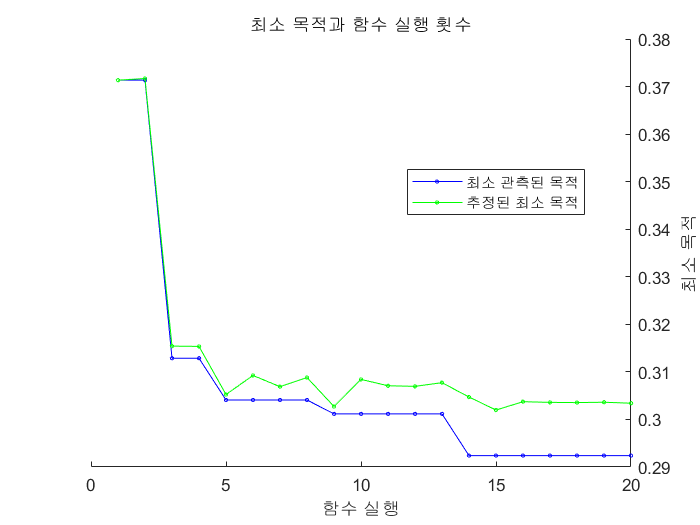


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 20회에 도달했습니다.
총 함수 실행 횟수: 20
총 경과 시간: 88.8544초
총 목적 함수 실행 시간: 6.6426

최선의 관측된 실현가능점:
    NumNeighbors    Distance     DistanceWeight    Exponent    Standardize
    ____________    _________    ______________    ________    ___________

         46         minkowski        equal         0.55532        false   

관측된 목적 함수 값 = 0.2924
추정된 목적 함수 값 = 0.30341
함수 실행 시간 = 0.26197

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors    Distance     DistanceWeight    Exponent    Standardize
    ____________    _________    ______________    ________    ___________

         46         minkowski        equal         0.55532        false   

추정된 목적 함수 값 = 0.30341
추정된 함수 실행 시간 = 0.28789



mdlknn_HO =   ClassificationKNN
                       PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
                         ResponseName: 'HeartDisease'
                CategoricalPredictors: []
                           ClassNames: [false    true]
                       ScoreTransform: 'none'
                      NumObservations: 342
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'minkowski'
                         NumNeighbors: 46


  Properties, Methods


errKNN_tr = resubLoss(mdlknn_HO)

errKNN_val = loss(mdlknn_HO,valData)


errKNN_tr = 0.3012

errKNN_val = 0.1883